# Power in AC circuits

## Instantaneous power

The instantaneous power is represented by p(t), and defined as:


$$p\left(t\right)=u\left(t\right)\;i\left(t\right)$$


With generic voltage and current signals, such as,

- 
$$u\left(t\right)=\sqrt{2}U\;\cos \left(\omega t+\theta_U \right)$$


- 
$$i\left(t\right)=\sqrt{2}I\;\cos \left(\omega t+\theta_I \right)$$


and using the equivalence $\cos \left(\theta_1 \right)\;\cos \left({\;\theta }_2 \right)=\frac{1}{2}\left(\cos \left({\;\theta }_1 +{\;\theta }_2 \right)+\cos \left({\;\theta }_1 -{\;\theta }_2 \right)\right),$

we obtain:

$p\left(t\right)=2\;U\;I\;\cos \left(\omega t+\theta_U \right)\;\cos \left(\omega t+\theta_I \right)=U\;I\;\cos \left(2\omega t+\theta_U +\theta_I \right)+U\;I\;\cos \left(\theta_U +\theta_I \right)$.

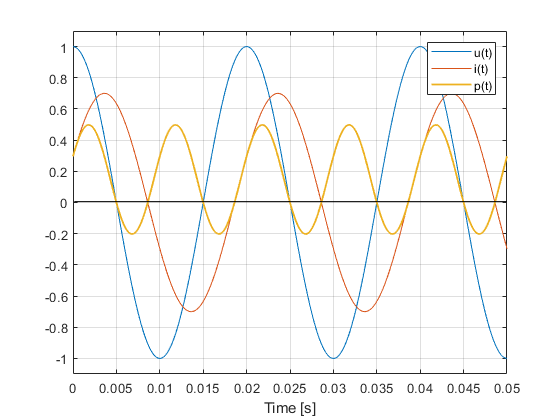

% Instantaneous power
t=0:0.0001:0.05;
omega=100*pi;

U=1/sqrt(2);
Uang=0;
u_t=U*sqrt(2)*cos(omega*t+Uang*pi/180);

I=0.7/sqrt(2);
Iang=-65;
i_t=I*sqrt(2)*cos(omega*t+Iang*pi/180);

p_t=u_t.*i_t;

title('Instantaneous power')
plot(t,u_t)
hold all
plot(t,i_t)
plot(t,p_t,'LineWidth',1.3)
legend('u(t)','i(t)','p(t)')
grid on
ylim([-1.1 1.1])
xlabel('Time [s]')
annotation('line',[0.1325 0.905],[0.52 0.52])